%% 初始化设置
% 设置中文显示
set(0, 'DefaultTextFontName', 'Kaiti');
set(0, 'DefaultAxesFontName', 'Kaiti');

%% 1. 生成模拟客户数据
rng(123);  % 设置随机种子

% 客户状态定义
customer_states = {'高频购买'; '低频购买'; '流失'};  % 1:高频, 2:低频, 3:流失

n_customers = 1000;  % 客户数量
n_months = 12;       % 时间跨度（月）

% 定义真实的客户行为转移概率矩阵
true_customer_matrix = [
    0.7, 0.2, 0.1;   % 高频 -> [高频, 低频, 流失]
    0.2, 0.5, 0.3;   % 低频 -> [高频, 低频, 流失]
    0.1, 0.2, 0.7];  % 流失 -> [高频, 低频, 流失]

%% 生成单个客户的状态轨迹函数
function journey = generate_customer_journey(n_months, true_matrix, initial_state)
    if nargin < 3 || isempty(initial_state)
        % 初始状态分布：30%高频，60%低频，10%流失
        initial_state = randsample(3, 1, true, [0.3, 0.6, 0.1]);
    end
    
    journey = zeros(1, n_months);
    journey(1) = initial_state;
    current_state = initial_state;
    
    for i = 2:n_months
        % 根据转移概率选择下一个状态
        probabilities = true_matrix(current_state, :);
        next_state = randsample(3, 1, true, probabilities);
        journey(i) = next_state;
        current_state = next_state;
    end
end

%% 生成所有客户的购买历史
% 初始化数据存储结构
customer_data = struct( ...
    'customer_id', [], ...
    'registration_months', [], ...
    'avg_order_value', [], ...
    'month', [], ...
    'purchase_count', [], ...
    'state', [], ...
    'state_name', [] ...
);

index = 1;
for customer_id = 1:n_customers
    % 生成客户状态轨迹
    journey = generate_customer_journey(n_months, true_customer_matrix);
    
    % 根据状态生成购买次数
    purchase_counts = zeros(1, n_months);
    for m = 1:n_months
        state = journey(m);
        if state == 1  % 高频购买
            count = poissrnd(5) + 4;  % 平均9次
        elseif state == 2  % 低频购买
            count = poissrnd(1.5) + 1;  % 平均2.5次
        else  % 流失
            count = 0;
        end
        purchase_counts(m) = count;
    end
    
    % 生成客户属性
    registration_months = randi([12, 36]);
    avg_order_value = normrnd(100, 30);
    
    % 创建月度记录
    for month = 0:n_months-1
        customer_data(index).customer_id = customer_id;
        customer_data(index).registration_months = registration_months;
        customer_data(index).avg_order_value = avg_order_value;
        customer_data(index).month = month;
        customer_data(index).purchase_count = purchase_counts(month+1);
        customer_data(index).state = journey(month+1);
        customer_data(index).state_name = customer_states{journey(month+1)};
        index = index + 1;
    end
end

% 显示数据概览
disp('客户数据概览：');

客户数据概览：


for i = 1:10
    disp(['客户ID: ', num2str(customer_data(i).customer_id), ...
          ', 月份: ', num2str(customer_data(i).month), ...
          ', 购买次数: ', num2str(customer_data(i).purchase_count), ...
          ', 状态: ', customer_data(i).state_name]);
end

客户ID: 1, 月份: 0, 购买次数: 2, 状态: 低频购买
客户ID: 1, 月份: 1, 购买次数: 3, 状态: 低频购买
客户ID: 1, 月份: 2, 购买次数: 1, 状态: 低频购买
客户ID: 1, 月份: 3, 购买次数: 3, 状态: 低频购买
客户ID: 1, 月份: 4, 购买次数: 0, 状态: 流失
客户ID: 1, 月份: 5, 购买次数: 0, 状态: 流失
客户ID: 1, 月份: 6, 购买次数: 0, 状态: 流失
客户ID: 1, 月份: 7, 购买次数: 0, 状态: 流失
客户ID: 1, 月份: 8, 购买次数: 0, 状态: 流失
客户ID: 1, 月份: 9, 购买次数: 0, 状态: 流失


disp(['数据形状：', num2str([length(customer_data), 7])]);

数据形状：12000      7


disp(['客户总数：', num2str(n_customers)]);

客户总数：1000


disp(['时间跨度：', num2str(n_months), '个月']);

时间跨度：12个月


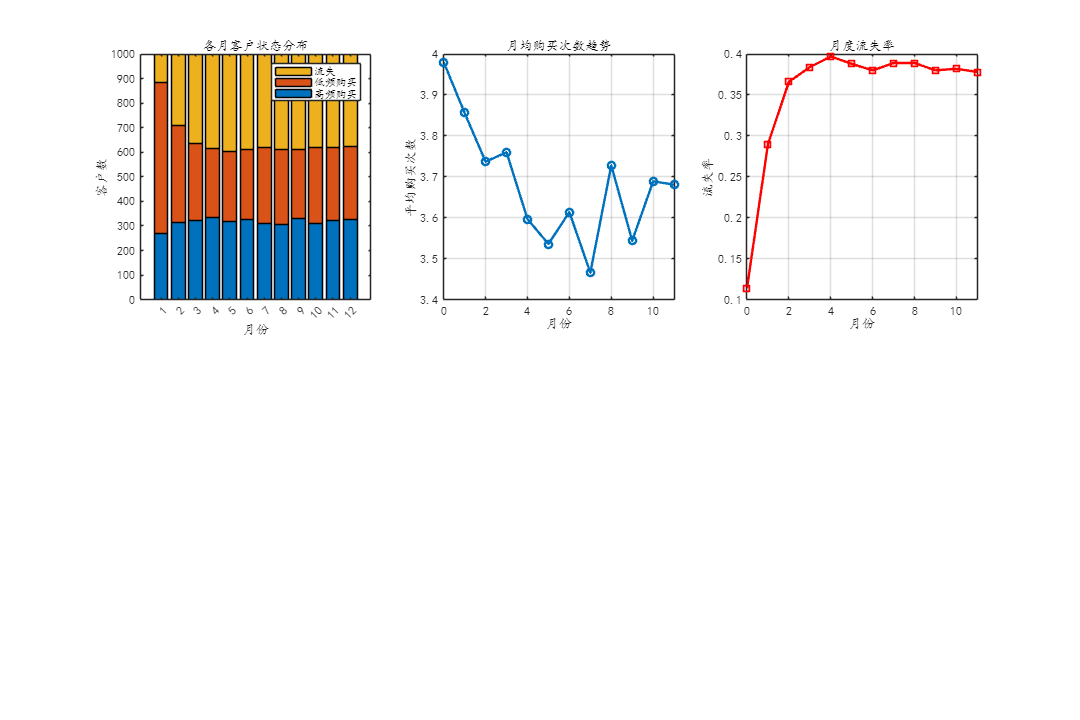

%% 2. 数据探索性分析

% 子图1：客户状态分布
figure('Position', [100, 100, 1200, 800]);
subplot(2, 3, 1);
state_counts = zeros(n_months, 3);
for month = 0:n_months-1
    for s = 1:3
        count = 0;
        for i = 1:length(customer_data)
            if customer_data(i).month == month && customer_data(i).state == s
                count = count + 1;
            end
        end
        state_counts(month+1, s) = count;
    end
end
bar(state_counts, 'stacked');
title('各月客户状态分布');
xlabel('月份');
ylabel('客户数');
legend(customer_states);

% 子图2：平均购买次数趋势
subplot(2, 3, 2);
monthly_avg = zeros(1, n_months);
for month = 0:n_months-1
    total = 0;
    count = 0;
    for i = 1:length(customer_data)
        if customer_data(i).month == month
            total = total + customer_data(i).purchase_count;
            count = count + 1;
        end
    end
    monthly_avg(month+1) = total / count;
end
plot(0:n_months-1, monthly_avg, 'o-', 'LineWidth', 2);
title('月均购买次数趋势');
xlabel('月份');
ylabel('平均购买次数');
grid on;
alpha(0.3);

% 子图3：客户流失率
subplot(2, 3, 3);
churn_rate = zeros(1, n_months);
for month = 0:n_months-1
    churn_count = 0;
    for i = 1:length(customer_data)
        if customer_data(i).month == month && customer_data(i).state == 3
            churn_count = churn_count + 1;
        end
    end
    churn_rate(month+1) = churn_count / n_customers;
end
plot(0:n_months-1, churn_rate, 's-', 'Color', 'r', 'LineWidth', 2);
title('月度流失率');
xlabel('月份');
ylabel('流失率');
grid on;

alpha(0.3);

%% 3. 构建马尔可夫模型
function [transition_matrix, transition_counts] = build_transition_matrix(data, n_states)
    transition_counts = zeros(n_states, n_states);
    
    % 获取所有客户ID
    customer_ids = unique([data.customer_id]);
    
    % 对每个客户追踪状态转移
    for id = customer_ids
        % 提取该客户的数据并按月份排序
        cust_indices = [data.customer_id] == id;
        cust_data = data(cust_indices);
        [~, order] = sort([cust_data.month]);
        cust_data = cust_data(order);
        
        % 提取状态序列
        states = [cust_data.state];
        
        % 统计转移
        for i = 1:length(states)-1
            from_state = states(i);
            to_state = states(i+1);
            transition_counts(from_state, to_state) = transition_counts(from_state, to_state) + 1;
        end
    end
    
    % 计算转移概率
    transition_matrix = zeros(n_states, n_states);
    for i = 1:n_states
        row_sum = sum(transition_counts(i, :));
        if row_sum > 0
            transition_matrix(i, :) = transition_counts(i, :) / row_sum;
        end
    end
end

%% 使用前8个月的数据训练模型
train_months = 8;
train_indices = [customer_data.month] < train_months;
train_data = customer_data(train_indices);
test_indices = [customer_data.month] >= train_months;
test_data = customer_data(test_indices);

[estimated_matrix, counts] = build_transition_matrix(train_data, 3);

disp(' ');

disp('估计的客户状态转移矩阵：');

估计的客户状态转移矩阵：


transition_table = array2table(estimated_matrix, ...
    'RowNames', customer_states, ...
    'VariableNames', customer_states);
disp(round(transition_table, 3));

               高频购买    低频购买    流失 
               _______    _______    _____

    高频购买      0.69      0.208     0.102
    低频购买     0.198      0.504     0.297
    流失        0.096        0.2     0.704



%% 4. 客户价值分析
function [clv, value_matrix] = calculate_customer_lifetime_value(transition_matrix, state_values, discount_rate, n_periods)
    n_states = length(state_values);
    
    % 构建价值矩阵
    value_matrix = zeros(n_periods, n_states);
    value_matrix(1, :) = state_values;
    
    % 计算未来各期的期望价值
    for t = 2:n_periods
        % 计算转移概率
        current_prob = eye(n_states);
        for p = 1:t-1
            current_prob = current_prob * transition_matrix;
        end
        
        % 计算折现价值
        discounted_values = state_values * (1 / (1 + discount_rate))^(t-1);
        value_matrix(t, :) = current_prob * discounted_values';
    end
    
    % 计算总的生命周期价值
    clv = sum(value_matrix, 1);
end

%% 定义各状态的月度价值（平均订单价值 × 购买次数）
state_monthly_values = [900, 250, 0];  % 高频、低频、流失

[clv, value_trajectory] = calculate_customer_lifetime_value( ...
    estimated_matrix, state_monthly_values, 0.1, 12);

disp(' ');

disp('客户生命周期价值（CLV）：');

客户生命周期价值（CLV）：


for i = 1:3
    fprintf('%s: ¥%.2f\n', customer_states{i}, clv(i));
end

高频购买: ¥3819.14
低频购买: ¥2451.58
流失: ¥1854.17


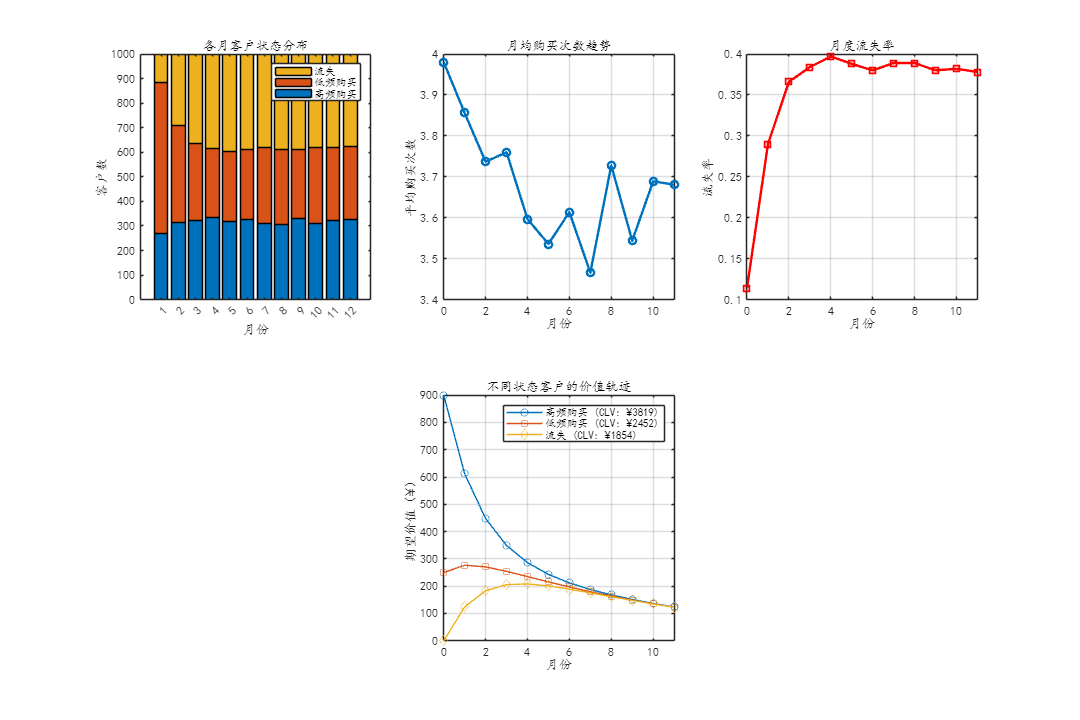


% 子图5：CLV轨迹
subplot(2, 3, 5);
months = 0:11;
markers = {'o', 's', 'd'};
for i = 1:3
    plot(months, value_trajectory(:, i), 'Marker', markers{i}, ...
        'DisplayName', sprintf('%s (CLV: ¥%.0f)', customer_states{i}, clv(i)));
    hold on;
end
xlabel('月份');
ylabel('期望价值（¥）');
title('不同状态客户的价值轨迹');
legend();
grid on;
alpha(0.3);
hold off;

%% 5. 营销策略优化
function results = simulate_marketing_intervention(transition_matrix, intervention_effect, target_state, n_customers, n_months, current_dist)
    % 修改转移矩阵以反映营销效果
    modified_matrix = transition_matrix;
    
    % 营销效果：降低流失概率，提高激活概率
    for state = 1:size(transition_matrix, 1)
        if modified_matrix(state, target_state) > intervention_effect
            % 减少流失概率
            modified_matrix(state, target_state) = modified_matrix(state, target_state) - intervention_effect;
            
            % 增加到其他状态的概率
            if state == target_state  % 如果是流失状态
                modified_matrix(state, 2) = modified_matrix(state, 2) + intervention_effect * 0.7;
                modified_matrix(state, 1) = modified_matrix(state, 1) + intervention_effect * 0.3;
            else
                modified_matrix(state, 3-state) = modified_matrix(state, 3-state) + intervention_effect;
            end
        end
    end
    
    % 模拟两种场景
    scenarios = {'no_intervention', 'with_intervention'};
    matrices = {transition_matrix, modified_matrix};
    
    results = struct();
    for s = 1:length(scenarios)
        matrix = matrices{s};
        dists = zeros(n_months+1, size(matrix, 1));
        dists(1, :) = current_dist;
        current = current_dist;
        
        for m = 1:n_months
            current = current * matrix;
            dists(m+1, :) = current;
        end
        
        results.(scenarios{s}) = dists;
    end
end

% 计算初始状态分布
initial_dist = zeros(1, 3);
last_train_month = train_months - 1;
for i = 1:length(customer_data)
    if customer_data(i).month == last_train_month
        state = customer_data(i).state;
        initial_dist(state) = initial_dist(state) + 1;
    end
end
initial_dist = initial_dist / sum(initial_dist);

% 模拟营销干预效果（减少10%的流失概率）
intervention_results = simulate_marketing_intervention( ...
    estimated_matrix, 0.1, 3, n_customers, 6, initial_dist);

% 子图6：营销效果对比
subplot(2, 3, 6);
months = 0:6;
colors = {'g', 'orange', 'r'};
linestyles = {'-', '--'};

for s = 1:2
    scenario_name = fieldnames(intervention_results)
    scenario_name = scenario_name{s};
    dists = intervention_results.(scenario_name);
    for i = 1:3
        if i == 3  % 只显示流失率
            plot(months, dists(:, i), 'Color', colors{i}, ...
                'LineStyle', linestyles{s}, ...
                'Marker', 'o', ...
                'DisplayName', sprintf('%s - %s', scenario_name, customer_states{i}), ...
                'LineWidth', 2);
            hold on;
        end
    end
end

scenario_name = 2×1 cell 数组
    {'no_intervention'  }
    {'with_intervention'}


scenario_name = 2×1 cell 数组
    {'no_intervention'  }
    {'with_intervention'}


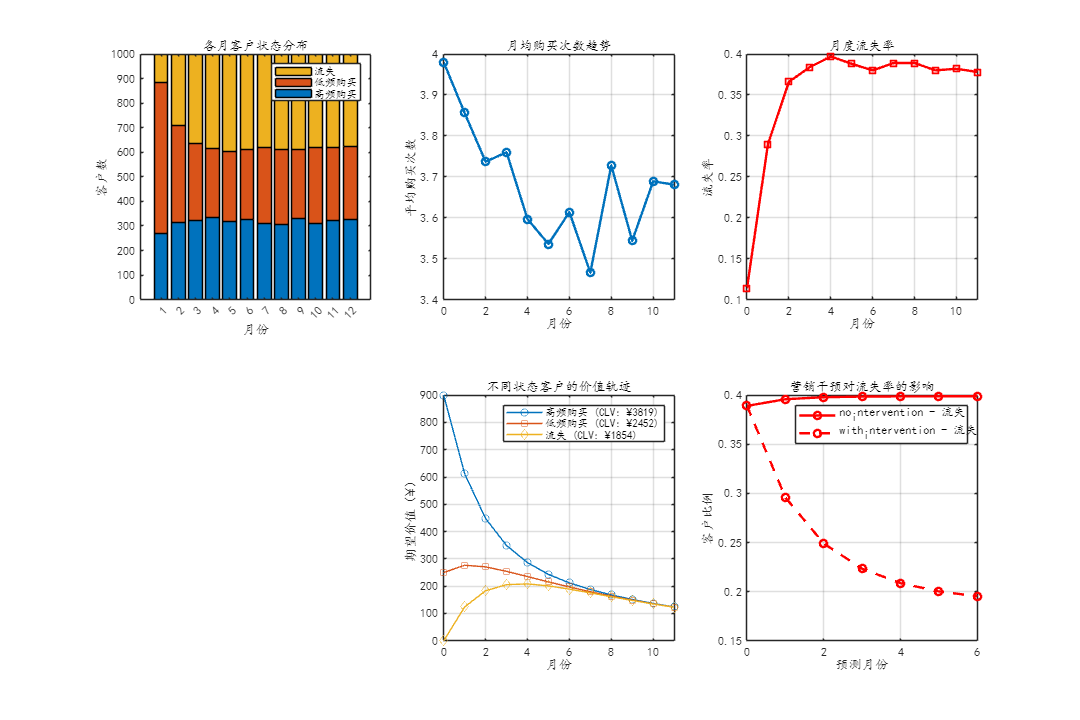

xlabel('预测月份');
ylabel('客户比例');
title('营销干预对流失率的影响');
legend();
grid on;
alpha(0.3);
hold off;

%% 6. 个体客户预测
function [predictions, probabilities] = predict_customer_state(customer_history, transition_matrix, n_months)
    current_state = customer_history(end);
    predictions = zeros(1, n_months);
    probabilities = zeros(n_months, size(transition_matrix, 1));
    
    % 当前状态的概率向量
    state_prob = zeros(1, size(transition_matrix, 1));
    state_prob(current_state) = 1.0;
    
    for m = 1:n_months
        % 计算下个月的状态概率
        state_prob = state_prob * transition_matrix;
        probabilities(m, :) = state_prob;
        
        % 预测最可能的状态
        [~, predicted_state] = max(state_prob);
        predictions(m) = predicted_state;
    end
end

% 选择几个典型客户进行预测
sample_customers = [1, 11, 51, 101];  % MATLAB索引从1开始
disp(' ');

disp('个体客户预测示例：');

个体客户预测示例：



for cust_id = sample_customers
    % 获取客户历史
    cust_indices = [train_data.customer_id] == cust_id;
    cust_data = train_data(cust_indices);
    [~, order] = sort([cust_data.month]);
    cust_data = cust_data(order);
    history = [cust_data.state];
    
    % 预测未来3个月
    [pred_states, pred_probs] = predict_customer_state(history, estimated_matrix, 3);
    
    fprintf('\n客户 %d:\n', cust_id);
    fprintf('  历史状态: ');
    for s = max(1, length(history)-2):length(history)
        fprintf('%s ', customer_states{history(s)});
    end
    fprintf('\n  预测状态: ');
    for s = 1:length(pred_states)
        fprintf('%s ', customer_states{pred_states(s)});
    end
    fprintf('\n  流失概率: ');
    for p = 1:size(pred_probs, 1)
        fprintf('%.4f ', pred_probs(p, 3));
    end
    fprintf('\n');
end


客户 1:


  历史状态: 

流失 流失 流失 


  预测状态: 

流失 流失 流失 


  流失概率: 

0.7038 0.5646 0.4928 


客户 11:


  历史状态: 

流失 低频购买 低频购买 


  预测状态: 

低频购买 流失 流失 


  流失概率: 

0.2973 0.3794 0.3997 


客户 51:


  历史状态: 

流失 流失 流失 


  预测状态: 

流失 流失 流失 


  流失概率: 

0.7038 0.5646 0.4928 


客户 101:


  历史状态: 

流失 高频购买 高频购买 


  预测状态: 

高频购买 高频购买 高频购买 


  流失概率: 

0.1019 0.2038 0.2770 

%% 7. 模型评估
function accuracy = evaluate_predictions(test_data, transition_matrix)
    correct_predictions = 0;
    total_predictions = 0;
    
    % 按客户分组
    customer_ids = unique([test_data.customer_id]);
    
    for id = customer_ids
        % 获取客户测试数据
        cust_indices = [test_data.customer_id] == id;
        cust_test = test_data(cust_indices);
        [~, order] = sort([cust_test.month]);
        cust_test = cust_test(order);
        
        if length(cust_test) < 2
            continue;
        end
        
        % 使用第一个测试月的状态预测后续
        initial_state = cust_test(1).state;
        actual_states = [cust_test(2:end).state];
        
        % 预测
        [pred_states, ~] = predict_customer_state([initial_state], transition_matrix, length(actual_states));
        
        % 计算准确率
        correct_predictions = correct_predictions + sum(pred_states == actual_states);
        total_predictions = total_predictions + length(actual_states);
    end
    
    if total_predictions > 0
        accuracy = correct_predictions / total_predictions;
    else
        accuracy = 0;
    end
end

accuracy = evaluate_predictions(test_data, estimated_matrix);
fprintf('\n模型预测准确率: %.2f%%\n', accuracy * 100);


模型预测准确率: 52.57%


%% 8. 策略建议
disp(' ');

disp('基于分析的营销策略建议：');

基于分析的营销策略建议：


disp(' ');

disp('1. 客户细分策略：');

1. 客户细分策略：


for i = 1:3
    fprintf('   - %s客户 (CLV: ¥%.0f)\n', customer_states{i}, clv(i));
end

   - 高频购买客户 (CLV: ¥3819)
   - 低频购买客户 (CLV: ¥2452)
   - 流失客户 (CLV: ¥1854)



disp(' ');

disp('2. 重点关注对象：');

2. 重点关注对象：


disp('   - 低频购买客户：流失风险高（30%），需要激活计划');

   - 低频购买客户：流失风险高（30%），需要激活计划


disp('   - 新流失客户：仍有10%概率重新激活');

   - 新流失客户：仍有10%概率重新激活



disp(' ');

disp('3. 建议的营销措施：');

3. 建议的营销措施：


disp('   - 对低频客户：个性化推荐、限时优惠');

   - 对低频客户：个性化推荐、限时优惠


disp('   - 对高频客户：VIP服务、忠诚度奖励');

   - 对高频客户：VIP服务、忠诚度奖励


disp('   - 对流失客户：召回邮件、特别折扣');

   - 对流失客户：召回邮件、特别折扣



% 保存分析结果
analysis_results.transition_matrix = estimated_matrix;
analysis_results.customer_lifetime_values = clv;
analysis_results.model_accuracy = accuracy;
analysis_results.intervention_simulation = intervention_results;
disp(analysis_results);

           transition_matrix: [3×3 double]
    customer_lifetime_values: [3.8191e+03 2.4516e+03 1.8542e+03]
              model_accuracy: 0.5257
     intervention_simulation: [1×1 struct]

